Model problem to test the leapfrogging method for the wave equation on the interval with Neumann boundary conditions implemented as a constraint on a grid with ghost points.

I'm solving

 
$$u_{tt} = \triangle u \\
u(0) = \psi_1(x) \\
\partial_t u(0) = \psi_2(x)$$


on the dumbbell graph with $L=2\pi$ on all edges. The functions defining the initial condition are numerically determined eigenfunctions with eigenvalues that approach -1 and -4 in the continuum limit. The solution to this IVP satisfies $u\left(x,\frac{\pi}{2} \right)=0.$Therefore the $L^\infty$error at $t=\frac\pi2$ is just the maximum of the absolute value.

We have chosen the graph, the edge lengths, and the initial conditions carefully. Because of the symmetry of the graph, then transforming the eigenfunction using a symmetry gives another eigenfunction, and adding these together gives an eigenfunction with an even symmetry, which we then normalize to unit norm. Without taking these steps, running the `eig` program on different systems may lead to different results.

The maximum error with 50 points/unit length is 4.959e-03.


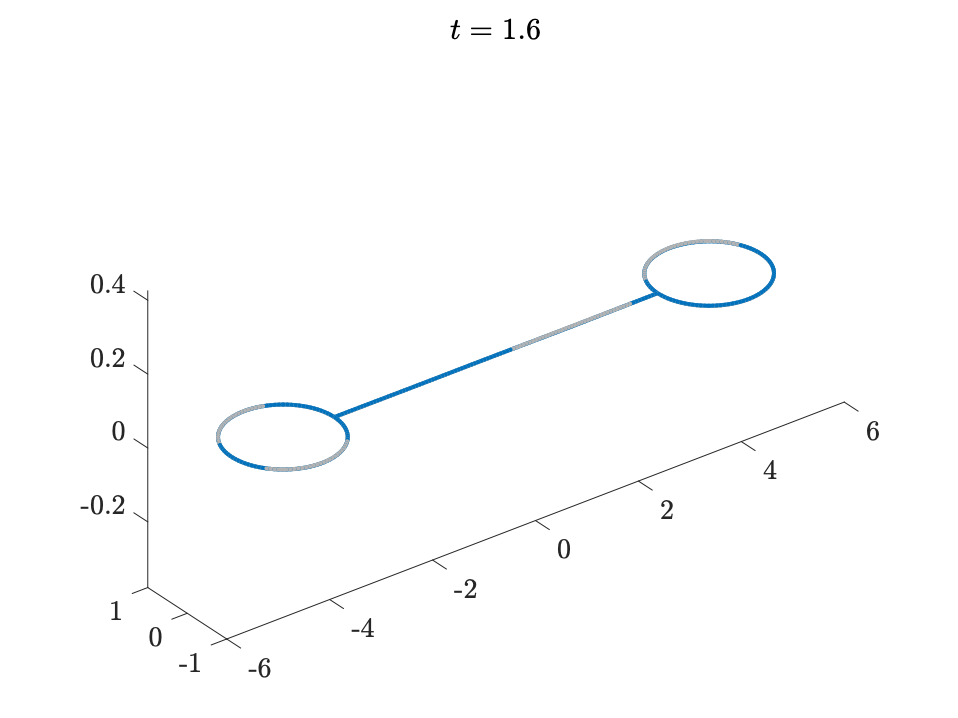

The maximum error with 100 points/unit length is 9.846e-04.


clear
tfinal = pi/2;
nx=50;
errorvec=zeros(1,2);
for j = 1:2
    Phi = quantumGraphFromTemplate('dumbbell','L',2*pi*[1 1 1],'nx',nx/2/pi);
    Phi.addPlotCoords(@dumbbellPlotCoords);
    nt = nx;
    h = tfinal/nt;
    L0 = Phi.laplacianMatrixWithZeros;
    P0 = Phi.interpolationMatrixWithZeros;
    PVC = Phi.interpolationMatrixWithVC;

    [V,lambda]=Phi.eigs(12);

    u0 = V(:,5)+flip(V(:,5));    u0 = u0/Phi.norm(u0);  % This corresponds to an eigenvalue approximately -1
    v0 = V(:,12)+flip(V(:,12));  v0 = v0/Phi.norm(v0);  % This corresponds to an eigenvalue approximately -4 

    u1 = PVC\(P0*(u0+h*v0))+(h^2/2)*(L0*u0);
    U = [u0 u1];
    for k=2:nt
        uNew = PVC\ (P0*(u1 + (u1-u0)) + h^2*L0*u1);
        u0 = u1;
        u1 = uNew;
        U = [U uNew];
    end
    t = linspace(0,1,nt+1)*pi/2;
    Phi.animatePDESolution(U,t,j);

    errorvec(j)=max(abs((u1)));
    fprintf('The maximum error with %i points/unit length is %0.3d.\n',nx,errorvec(j))
    nx = 2*nx;
end

order = log2(errorvec(1)/errorvec(2));
fprintf('The approximate order of convergence is %0.3g.\n',order)

The approximate order of convergence is 2.33.
